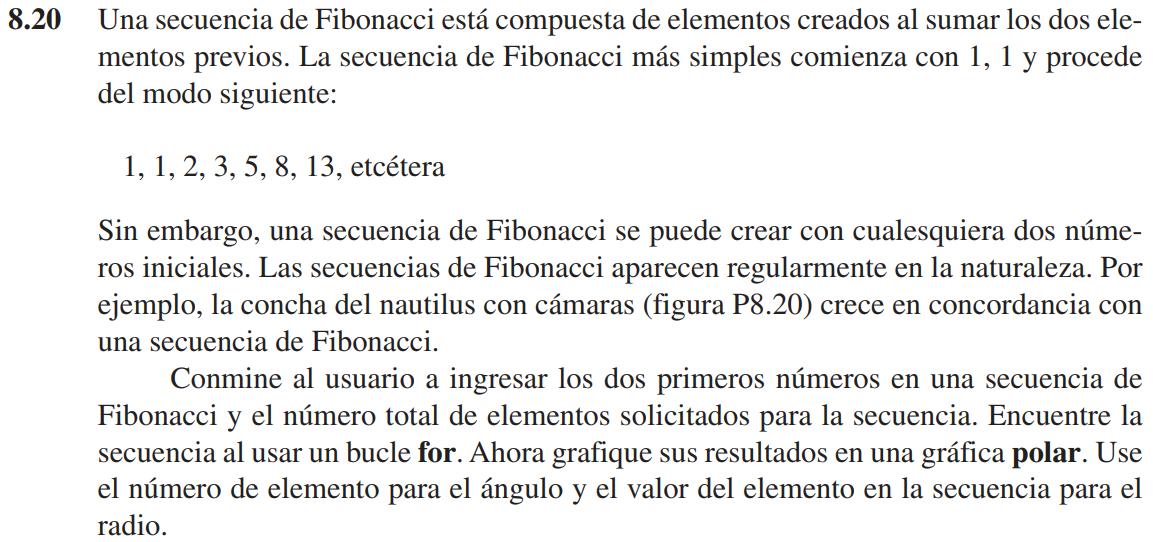

clear

n1 = input('Ingresar un número de Fibonacci: ');
n2 = input('Ingresar un número de Fibonacci consecutivo al anterior: ');
n = input('¿Cuántos números debe tener la serie?: ');
fiboNumber = [n1 n2 zeros(1,n-2)];

for i = 1:n-2
    fiboNumber(i+2) = fiboNumber(i) + fiboNumber(i+1);
end

disp(fiboNumber)
polarplot(1:length(fiboNumber),fiboNumber)

clear

n1 = input('Ingresar un número de Fibonacci: ');
n2 = input('Ingresar un número de Fibonacci consecutivo al anterior: ');
n = input('¿Cuántos números debe tener la serie?: ');
fiboNumber = [n1 n2 zeros(1,n-2)];
i = 1;

while i <= length(fiboNumber) - 2
    fiboNumber(i+2) = fiboNumber(i) + fiboNumber(i+1);
    i = i + 1
end

disp(fiboNumber)

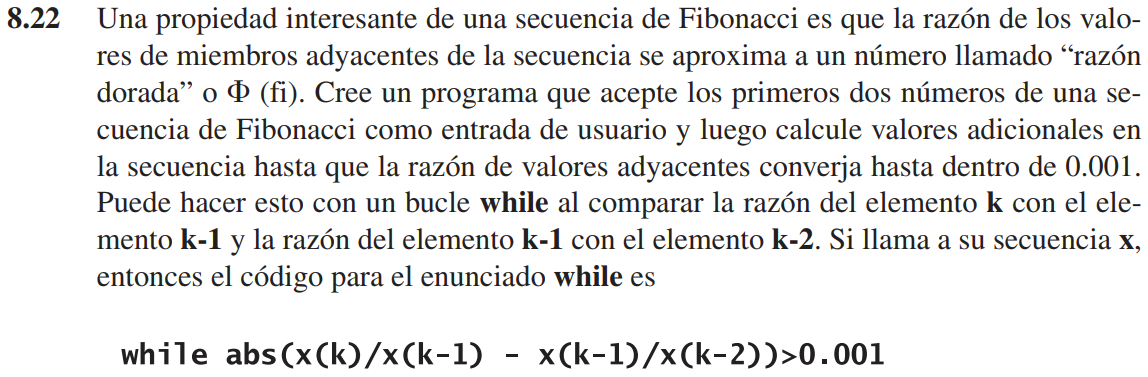

clear

n1 = input('Ingresar un número de Fibonacci: ');
n2 = input('Ingresar un número de Fibonacci consecutivo al anterior: ');
x = [n1 n2 n1+n2];
k = 1;

while abs(x(k+2)/x(k+1) - x(k+1)/x(k)) > .001
    x(k+3) = x(k+2) + x(k+1);
    k = k + 1;
end

disp(x)

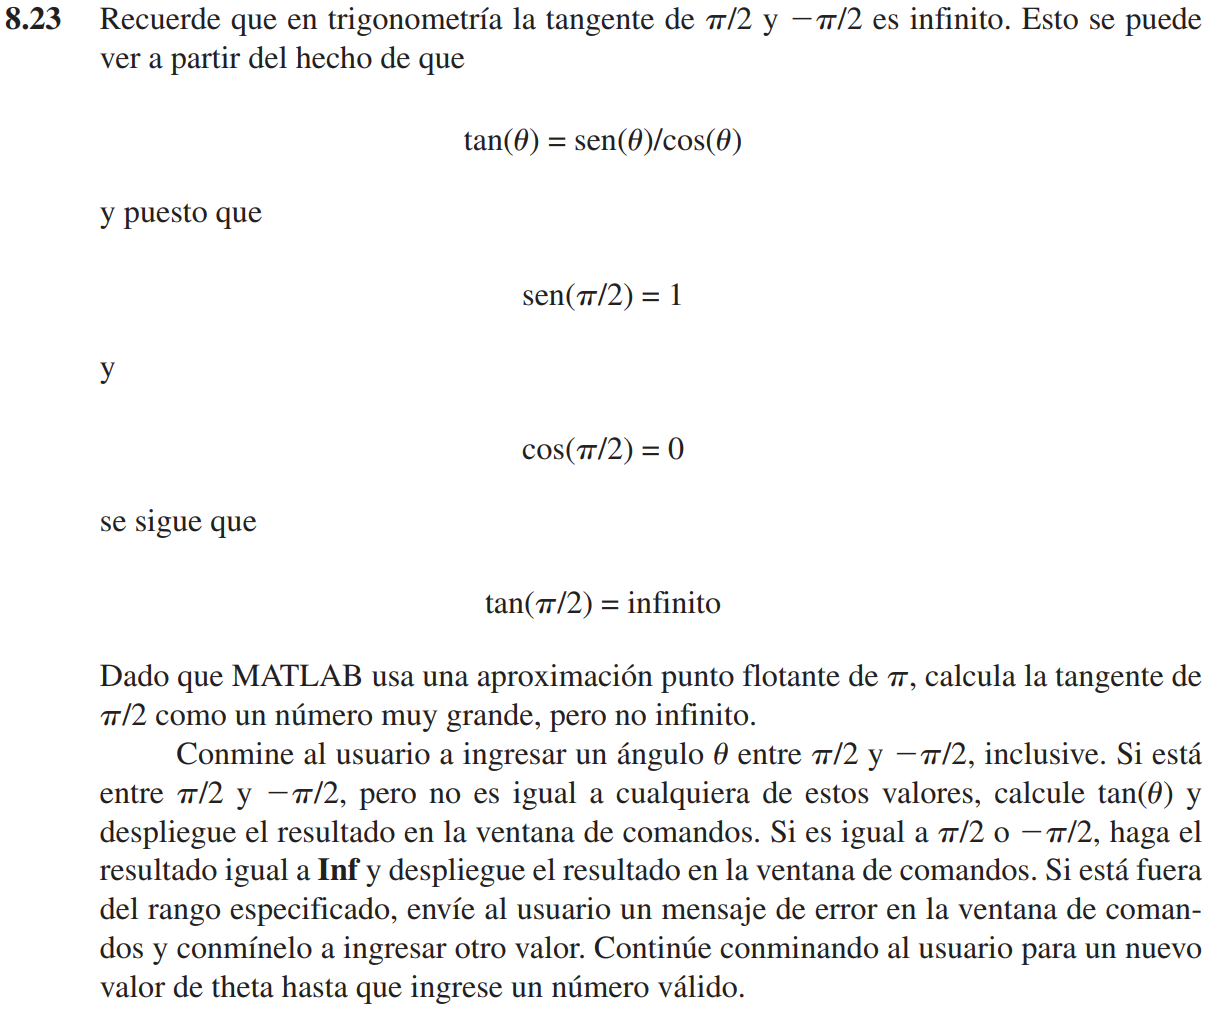

clear

theta = deg2rad(input('Ingresar un ángulo entre 90° y -90°: '));

while theta > pi/2 || theta < -pi/2
    theta = deg2rad(input('Ingresar un ángulo entre 90° y -90°: '));
end

if theta ~= -pi/2 && theta ~= pi/2
    result = tan(theta);
else
    result = inf;
end

fprintf('La tangente de %.1f° es %.2f.',rad2deg(theta),result)